# Assignment #4: dynamic programming

## Group information

Group number: 46

Students:

- Matteo Canestrini, s349238

- Dennis Bettinsoli, s357720

- Simone Massucco, s357725

## Implement Dynamic Programming

This report illustrates how to solve the energy management problem by using an optimization technique called Dynamic Programming (DynaProg), in order to minimize the total fuel consumed over the WLTP cycle. At each one-second timestep, the algorithm evaluates the optimal gear and the torque split factor between the internal combustion engine and the electric motor.

The problem is mathematically mapped onto the DynaProg solver through the following variable definitions:  

**1. State Variable and Grid Setup**

The only state variable for the base problem is the battery State of Charge (SOC), as its value directly affects the feasible operations of the next stage through the battery charge balance.  

- **Grid discretization:** the SOC grid was defined from 0.4 to 0.8 with a step of 0.005. This specific range efficiently bounds the usable battery capacity, avoiding computational waste on unfeasible extremes (e.g., completely full or empty battery), while the 0.5% resolution provides enough granularity to accurately track the charge trajectory.

- **Boundary conditions:** The initial state is strictly set to 60% ( $\sigma_{0} = 0.60$ ). To satisfy the charge-sustaining requirement of the HEV, the final state is constrained within a narrow band of [0.60 0.62] ( $\sigma_{N} \ge 60$ ).  

**2. Control Variables and Operating Modes**

The control variables are the gear number ( $\gamma$ ) and the torque-split factor ( $\alpha_{eng}$ ). The engine alpha dictates the share of demanded torque provided by the engine, effectively setting the powertrain operating mode.  

- **Gear Grid:** the gamma set was constrained between 1 and 6.

- **Alpha Grid:** $\alpha_{eng}$ was linearly spaced from 0 to 2.5 using exactly 51 elements (step size of 0.05). This specific array size was chosen to land exactly on the integer and critical values: $\alpha = 0$ (Pure Electric), $\alpha = 1$ (Pure Thermal), $0 < \alpha < 1$ (Power Split), and $\alpha > 1$ (Battery Charging via the engine). Including exactly 1 ensures that the solver can easily access the optimal pure thermal mode without interpolation approximations.

The solver requires the quantities as state variables, control variables and exogenous input to be formatted strictly as cell arrays. The specific inputs passed to the DynaProg initialization function are defined as follows:

- **Stategrid**: A cell array containing the discretised state space vector. In this base configuration, it contains only the battery SOC grid, defined as {SOC}.  

- **Stateinitial**: A cell array specifying the initial conditions of the system at the first stage, set to {SOC_0}.  

- **Statefinal**: A cell array enforcing the terminal constraints at the end of the driving cycle. It is defined as {SOC_bounds}, ensuring the vehicle satisfies the charge-sustaining requirement.  

- **Controlgrid**: A cell array containing the discretised control variables available to the optimizer at each step, passed as {gamma, alpha}.  

- **Nstages**: A scalar value representing the total number of decision intervals over the optimization horizon, calculated as the length of the time vector minus one (length(time) - 1).  

- **SysName**: The system model provided as an anonymous function handle, @(x, u, w) hev_cell_model(x, u, w, veh). DynaProg always calls it as f(x,u,w); the vehicle data `veh` is bound inside the anonymous function, so it travels with the handle without being a state, a control or an exogenous input.

- **ExogenousInput**: Passed as a name-value pair argument, it is a cell array containing the time-series profiles of the external variables, {vehSpd, vehAcc}, which are sampled by the solver stage by stage. 

Therefore,` prob = run(prob)` sweeps the cycle backwards to build the cost-to-go table, then forwards from SOC_0 to extract the optimal sequence. After the run it was read the solution from the prob object: 

- `prob.StateProfile` holds the optimal SOC trajectory;

- `prob.ControlProfile` holds the optimal gear and alpha sequences;

- `prob.AddOutputsProfile` holds the four model output structures (engine, e-machine, battery, vehicle) at every second. 

close all
clc
clear
addpath(genpath(fullfile("..", "Common")));
mission = load('WLTP.mat');
Cycle_name = {'WLTP'};
veh = load("vehData.mat");                      % import the vehicle data
veh = scaleVehData(veh,118000,27000,2100);      % scale the data

vehSpd = mission.speed_km_h ./ 3.6;         % vehicle speed in (m/s)
vehAcc = mission.acceleration_m_s2;         % vehicle acceleration in (m/s^2)
time = mission.time_s;                      % mission time in (s)
veh.dt = 1; 


% Control grid

gamma_min = 1;
gamma_max = 6; 
gamma = gamma_min : gamma_max;                % possible gear numbers
alpha = linspace(0, 2.5, 51);                 % possible torque-split factors (step = 0.05)
SOC = 0.4 : 0.005: 0.8;
SOC_bounds = [0.60 0.62];
SOC_0 = 0.6;

% Cell arrays - input of Dynaprog 

Stategrid = {SOC};
Stateinitial = {SOC_0};
Statefinal = {SOC_bounds};
Controlgrid = {gamma,alpha};
Nstages = length(time)-1;
ExoInput = {vehSpd(1:Nstages), vehAcc(1:Nstages)};
SysName = @(x, u, w) hev_cell_model(x, u, w, veh);

prob = DynaProg(Stategrid, Stateinitial, Statefinal, Controlgrid, Nstages, SysName,'ExogenousInput',ExoInput);
prob = run(prob);

DP backward progress:100 %
DP forward progress:100 %


### Save results

The four output structures come back as struct arrays over the cycle. The structArray2struct turns each one into a scalar structure of vectors, which is easier to slice and plot, and we pack them into prof. We then compute the cycle totals (fuel mass, distance, fuel economy in l/100km, final SOC) and the two drivability indicators (gear shifts and engine starts per minute), and store everything in `results_base.mat`. A gear shift is any change of gear between few seconds; an engine start is a 0 to 1 transition of the engine-on signal, which here is alpha > 0. 

To provide an immediate, structured overview of the vehicle performance, the script generates and displays a `table` object (`T_results`) in the command window. This summary table explicitly logs the driving cycle name along with all the key performance indicators calculated: Total Fuel Consumption (kg), Fuel Economy (l/100km), Final SOC, Gear Shifts per minute, and Engine Starts per minute.

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.

engPrf = structArray2struct(prob.AddOutputsProfile{1});
emPrf = structArray2struct(prob.AddOutputsProfile{2});
battPrf = structArray2struct(prob.AddOutputsProfile{3});
vehPrf = structArray2struct(prob.AddOutputsProfile{4});
% Pack profiles into a single structure
prof.engPrf = engPrf;
prof.emPrf = emPrf;
prof.battPrf = battPrf;
prof.vehPrf = vehPrf;

% Calculate total fuel consumption in kg
fuelConsumption = trapz(time(1:end-1),engPrf.fuelFlwRate)/1000; 

% Calculate total distance in km 
distance = trapz(time, vehSpd) / 1000; 

% Calculate total fuel volume in liters
fuel_volume = fuelConsumption / veh.eng.fuelDensity;

% Calculate fuel economy in l/100km
fuelEconomy = (fuel_volume / distance) * 100; 

% Get final state of charge
finalSOC = prof.battPrf.battSOC(end); 

% Drivability: Gear shifts and engine starts
nS_base = sum(diff(prof.vehPrf.gearNumber) ~= 0);
gearShiftAvg_base = nS_base / time(end-1) * 60;

engine_state_base = prob.ControlProfile{2,1} > 0;
nStart_base = sum(diff(double(engine_state_base)) == 1);
engineStartAvg_base = nStart_base / time(end-1) * 60;

%% Summary table
T_results = table(Cycle_name,fuelConsumption, fuelEconomy, finalSOC, gearShiftAvg_base, engineStartAvg_base, ...
    'VariableNames', {'Cycle','Fuel Consumption (kg)','Fuel Economy (l/100km)','SOC_final', 'Shifts/min', 'Starts/min'});

disp(T_results);

     Cycle      Fuel Consumption (kg)    Fuel Economy (l/100km)    SOC_final    Shifts/min    Starts/min
    ________    _____________________    ______________________    _________    __________    __________

    {'WLTP'}           0.83332                   4.5634             0.60929       14.441        2.1012  



% Store results
save("results_base.mat", "prof", "fuelConsumption", "fuelEconomy", "finalSOC","gearShiftAvg_base", "engineStartAvg_base"); 


## Post processing

The plots below summarise the fuel-optimal solution without any drivability constraint. Read together, they show a strategy that is efficient on fuel but shifts gears and restarts the engine far too often to be acceptable in a real car.

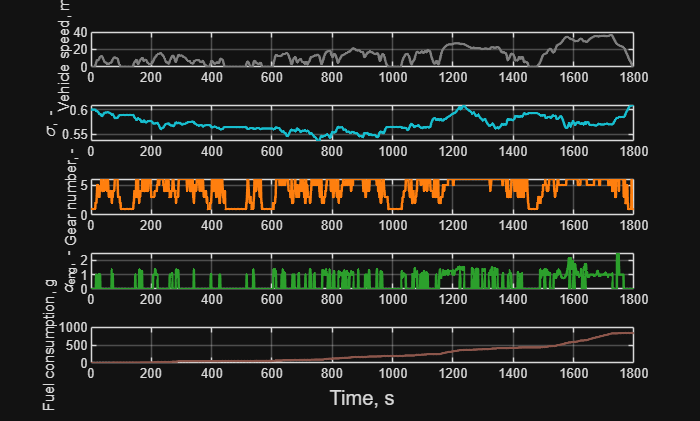

% Velocity, fuel consumption, SOC, gear profile
mainProfiles(prof);

***Main Profiles over time.*** The vehicle speed (top) is the WLTP demand. The SOC stays close to the 60% start and drifts inside a narrow band between about 0.55 and 0.61, so the strategy is charge sustaining. The gear shift trace is restless: it jumps between gears almost every second. The torque-split alpha switches on and off constantly, which is the engine being pulsed on for short bursts. The cumulative fuel (bottom) grows in steps that line up with the higher-speed, higher-load parts of the cycle.

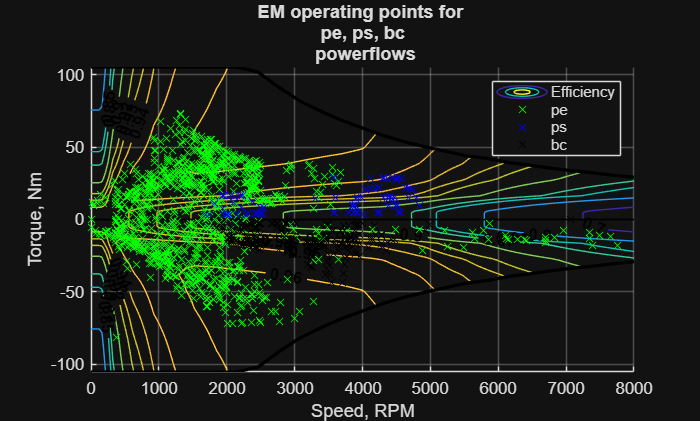

% Plot e-Machine operating points over its efficiency map
emMapWithPF(veh.em, prof);

***E-machine operating points over its efficiency map.*** Points with positive torque are motor assist or pure electric traction; points with negative torque are regenerative braking and battery charging. The overall operating points spread over a wide speed range and sit mostly in the high-efficiency region (0.9 and above), which is expected since the optimiser is free to pick the best gear for the motor at every instant.

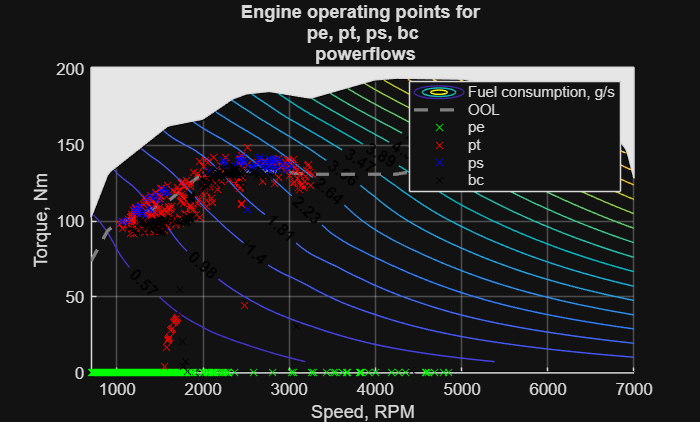

% Plot ICE operating points over the Fuel Consumption (FC) map 
engMapWithPF(veh.eng,prof,"fc","all");

***Engine operating points over the fuel-consumption map, with the optimal operating line (OOL  - the dashed line).*** The loaded points cluster around the OOL in the efficient mid-load region, which is the signature of a fuel-optimal policy: when the engine runs, it runs where it is efficient. The scattered low-torque points come from the many short engine starts, where the engine is switched on briefly and works away from its best line.

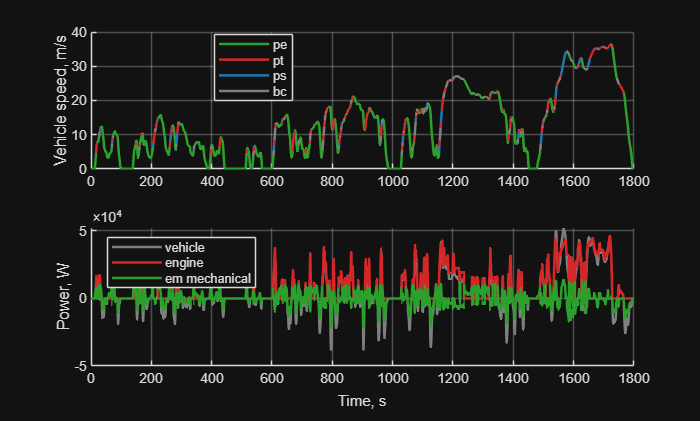

% Plot power profiles to inspect the 4 operating conditions
powerProfiles(prof);

***Power flows over time.*** The top panel colors the speed trace by operating mode; the bottom panel shows vehicle, engine and e-machine mechanical power. The engine covers the high-power demands, the e-machine handles low loads and recovers energy under braking (negative power), and the frequent color changes in the top panel mirror the constant mode switching seen in the main profile.

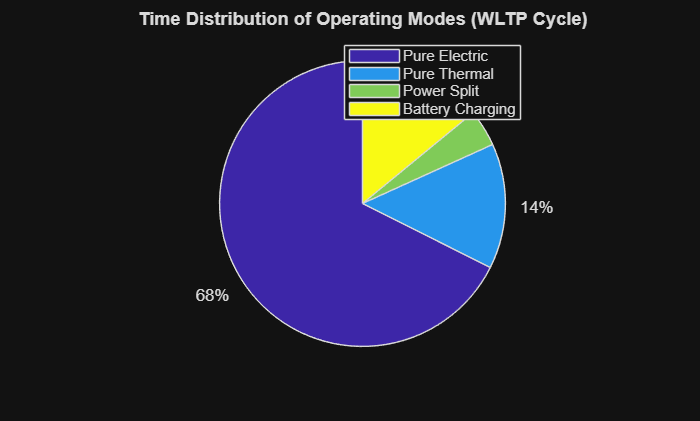

% EXTRA PLOT 1: Operating Modes Distribution
% Calculate the time spent in each operating mode by analyzing the array of
% the engine split factor alpha
% Count the number of seconds for each condition
time_PE = sum(prob.ControlProfile{2,1} == 0); % Pure Electric: alpha is exactly 0
time_PT = sum(prob.ControlProfile{2,1} == 1); % Pure Thermal: alpha is exactly 1
time_PS = sum(prob.ControlProfile{2,1} > 0 & prob.ControlProfile{2,1} < 1); % Power Split: alpha is between 0 and 1
time_BC = sum(prob.ControlProfile{2,1} > 1); % Battery Charging: alpha is strictly greater than 1

% Create the Pie Chart
figure
labels = {'Pure Electric', 'Pure Thermal', 'Power Split', 'Battery Charging'};
% The pie function automatically calculates the percentages based on the given array
pie([time_PE, time_PT, time_PS, time_BC]);
legend(labels)
title('Time Distribution of Operating Modes (WLTP Cycle)');  

This pie chart shows the share of cycle time per operating mode. Pure electric dominates at about 68%, with pure thermal around 14% and the rest split between power split and battery charging. The car spends most of the cycle on the e-motor and switch on the engine only for the demanding sections, which is consistent with a small e-machine and a fuel-minimising objective.

## Fuel-optimal EMS with drivability

The baseline DynaProg solution is feasible but not drivable, resulting in 433 gear shifts (14.44 per minute) and 63 engine starts (2.10 per minute) over the driving cycle. A real driver would not tolerate this engine behavior. Therefore, to improve drivability while maintaining the same physical model, the **stage cost function** was modified. By introducing a penalty for these transitions, the optimizer is forced to suppress the unwanted behavior:


$$\[
L = \dot{m_f} \cdot dt + c_1 \cdot (\gamma \neq \gamma_{prev}) + c_2 \cdot (\alpha > 0 \ \& \  \epsilon_{prev} = 0)
\]$$


c1 is charged whenever the chosen gear differs from the previous one, that is on every gear shift. c2 is charged on an engine start, defined as the engine being on now (alpha > 0) while it was off at the previous second ( $\epsilon_{prev} = 0$ ).

The stage cost can only depend on the current state, control and exogenous input. The previous gear and the previous engine state are not among them, so they were added as two extra states. Their dynamics function as simple state updates: the current gear selection and engine-on flag are stored to define the previous gear and engine state for the subsequent time step.

- New state gamma_prev, with `gamma_prev(k+1) = gamma(k)`. Grid 1:6.

- New state eps_prev, with `eps_prev(k+1) = (alpha(k) > 0)`. Grid [0 1].

These modifications are implemented within a dedicated model function, hev_cell_model_penalty.m. This updated function introduces two additional entries within the x_next cell array (x_next{2} and x_next{3}) to handle state transitions. Furthermore, it incorporates the augmented stage cost formulation and receives the penalty gains $c_1$ and $c_2$ as input arguments. The DynaProg call remains identical to the one in Part 1, but now operating with three states. Only the SOC is subject to a final constraint; $\gamma_{prev}$ and $\varepsilon_{prev}$ are left unconstrained at the final time step (corresponding to empty entries in Statefinal), as the terminal gear and engine states do not affect the objective function. Incorporating these two additional states expands the state grid from 81 to $81 \times 6 \times 2 = 972$ nodes. This computational expansion represents the trade-off required to integrate drivability directly into the optimization process rather than applying it as a post-hoc filter.

### Tuning of c1 and c2 

A higher penalty gain reduces the frequency of gear shifts or engine starts at the expense of fuel economy, highlighting a clear trade-off between these competing objectives. The calibration of $c_1$ and $c_2$ was performed via a trial-and-error heuristic, increasing each parameter until the respective transition rate dropped below the target threshold of one event per minute while minimizing the fuel penalty. The final selection settled on $c_1 = 0.6$ and $c_2 = 0.3$, resulting in 0.87 shifts/min and 0.80 starts/min over the WLTP cycle. Further increases in the gains yielded marginal drivability improvements at a disproportionate cost in fuel consumption, identifying these values as the optimal trade-off point.

### Trade-off analysis: sweep of the penalty gains c1 and c2

The penalty gains $c_1$ and $c_2$ were calibrated in the previous section through a trial-and-error procedure. This section makes the compromise explicit by quantifying how fuel economy responds to drivability: the dynamic program is solved again for a range of penalty gains, and the resulting fuel economy is traced against the target transition rate.

To keep the analysis independent with respect to the previous sections, the three-state penalty problem (battery SOC, previous gear and previous engine state) is rebuilt locally before the sweep, retaining the selected operating point ( $c_1 = 0.6$, $c_2 = 0.3$ ) as the reference. Moreover, the sweep adopts the widened final SOC band [0.60, 0.63]; the rationale for this choice is discussed in the next section. The trade-off is then explored through two independent one-at-a-time sweeps, so that the effect of each gain can be isolated:

- ***Gear-shift gain***: $c_1$ is swept over [${0.2, 0.6, 1.0}$] while $c_2$ is held at its selected value of $0.3$, isolating its effect on the gear-shift frequency;

- ***Engine-start gain***: $c_2$ is swept over [${0.1, 0.3, 0.5}$] while $c_1$ is held at its selected value of $0.6$, isolating its effect on the engine-start frequency;

For every gain, DynaProg is solved from scratch and the same key performance indicators used throughout the script (fuel economy in l/100km, gear shifts per minute and engine starts per minute) are recomputed, so that the results are directly comparable with the rest of the report. The gains were kept moderate and chosen to bracket the selected operating point, which also limits the computational effort to six Dynamic-Programming solves. The outcome of each sweep is collected in a summary table and visualised as a trade-off curve.

% Re-solves the DynaProg problem for a few (non-extreme) penalty gains to quantify the fuel-vs-drivability trade-off.
% The 3-state penalty problem is rebuilt locally (suffix _sw) so this section runs independently of which section was executed last. 
% It reuses only data already defined earlier: SOC, gamma, alpha, time, vehSpd, vehAcc, veh.

c1_nom = 0.6;        % selected gear-shift penalty
c2_nom = 0.3;        % selected engine-start penalty

% 3-state penalty problem (SOC, previous gear, previous engine state)
Stategrid_sw    = {SOC, 1:6, [0 1]};
Stateinitial_sw = {0.6, 1, 0};
Statefinal_sw   = {[0.60 0.63], [], []};   % only SOC constrained at the final stage
Controlgrid_sw  = {gamma, alpha};
Nstages_sw      = length(time) - 1;
ExoInput_sw     = {vehSpd(1:Nstages_sw), vehAcc(1:Nstages_sw)};
distance        = trapz(time, vehSpd) / 1000;   % cycle distance [km] (constant)
label           = {'First','Second','Third'};   % (only for comments in the code)

% % Sweep on c1 (gear-shift penalty), c2 fixed
c1_values = [0.2, 0.6, 1.0];
fuelEco_c1 = zeros(numel(c1_values),1);
shifts_c1  = zeros(numel(c1_values),1);
starts_c1  = zeros(numel(c1_values),1);

for k = 1:numel(c1_values)
    c1_k = c1_values(k);
    SysName_k = @(x,u,w) hev_cell_model_penalty(x,u,w,veh,c1_k,c2_nom);
    prob_k = DynaProg(Stategrid_sw, Stateinitial_sw, Statefinal_sw, Controlgrid_sw, ...
                      Nstages_sw, SysName_k, 'ExogenousInput', ExoInput_sw);
    prob_k = run(prob_k);

    toVideo = sprintf('\n ...%s DP simulation done... \n',label{k});
    disp(toVideo)

    engPrf_k = structArray2struct(prob_k.AddOutputsProfile{1});
    vehPrf_k = structArray2struct(prob_k.AddOutputsProfile{4});
    fuelMass = trapz(time(1:end-1), engPrf_k.fuelFlwRate) / 1000;          % kg
    fuelEco_c1(k) = (fuelMass / veh.eng.fuelDensity / distance) * 100;     % l/100km
    shifts_c1(k)  = sum(diff(vehPrf_k.gearNumber) ~= 0) / time(end-1) * 60;
    engOn_k       = prob_k.ControlProfile{2,1} > 0;
    starts_c1(k)  = sum(diff(double(engOn_k)) == 1) / time(end-1) * 60;
end

DP backward progress:100 %
DP forward progress:100 %



 ...First DP simulation done... 



DP backward progress:100 %
DP forward progress:100 %



 ...Second DP simulation done... 



DP backward progress:100 %
DP forward progress:100 %



 ...Third DP simulation done... 




% % Sweep on c2 (engine-start penalty), c1 fixed 
c2_values = [0.1, 0.3, 0.5];
fuelEco_c2 = zeros(numel(c2_values),1);
shifts_c2  = zeros(numel(c2_values),1);
starts_c2  = zeros(numel(c2_values),1);

for k = 1:numel(c2_values)
    c2_k = c2_values(k);
    SysName_k = @(x,u,w) hev_cell_model_penalty(x,u,w,veh,c1_nom,c2_k);
    prob_k = DynaProg(Stategrid_sw, Stateinitial_sw, Statefinal_sw, Controlgrid_sw, ...
                      Nstages_sw, SysName_k, 'ExogenousInput', ExoInput_sw);
    prob_k = run(prob_k);

    toVideo = sprintf('\n ...%s DP simulation done... \n',label{k});
    disp(toVideo)

    engPrf_k = structArray2struct(prob_k.AddOutputsProfile{1});
    vehPrf_k = structArray2struct(prob_k.AddOutputsProfile{4});
    fuelMass = trapz(time(1:end-1), engPrf_k.fuelFlwRate) / 1000;
    fuelEco_c2(k) = (fuelMass / veh.eng.fuelDensity / distance) * 100;
    shifts_c2(k)  = sum(diff(vehPrf_k.gearNumber) ~= 0) / time(end-1) * 60;
    engOn_k       = prob_k.ControlProfile{2,1} > 0;
    starts_c2(k)  = sum(diff(double(engOn_k)) == 1) / time(end-1) * 60;
end

DP backward progress:100 %
DP forward progress:100 %



 ...First DP simulation done... 



DP backward progress:100 %
DP forward progress:100 %



 ...Second DP simulation done... 



DP backward progress:100 %
DP forward progress:100 %



 ...Third DP simulation done... 




% % Summary tables
T_c1 = table(c1_values(:), shifts_c1, starts_c1, fuelEco_c1, ...
    'VariableNames', {'c1 (c2=0.3)','Shifts_min','Starts_min','Fuel_l_100km'});
T_c2 = table(c2_values(:), shifts_c2, starts_c2, fuelEco_c2, ...
    'VariableNames', {'c2 (c1=0.6)','Shifts_min','Starts_min','Fuel_l_100km'});
disp(T_c1);

    c1 (c2=0.3)    Shifts_min    Starts_min    Fuel_l_100km
    ___________    __________    __________    ____________

        0.2          1.3341       0.80044         4.6193   
        0.6         0.86715       0.80044         4.6377   
          1         0.76709       0.86715          4.645   



disp(T_c2);

    c2 (c1=0.6)    Shifts_min    Starts_min    Fuel_l_100km
    ___________    __________    __________    ____________

        0.1         0.86715        1.1673         4.6297   
        0.3         0.86715       0.80044         4.6377   
        0.5          0.9005       0.63369         4.6451   




% %  Trade-off plots
figure('Name','Fuel vs drivability trade-off','NumberTitle','off')
tg = tiledlayout(1,2);

nexttile     % c1: fuel economy vs gear shifts per minute
plot(shifts_c1, fuelEco_c1, '-o', 'LineWidth', 1.1); hold on
for k = 1:numel(c1_values)
    text(shifts_c1(k), fuelEco_c1(k), sprintf('  c_1=%.1f', c1_values(k)));
end
idx = find(c1_values == c1_nom, 1);
plot(shifts_c1(idx), fuelEco_c1(idx), 'o','MarkerFaceColor', 'g', 'MarkerEdgeColor', 'g')
xline(1, '--', '< 1/min target','Color', [0.5 0.5 0.5],'LabelHorizontalAlignment', 'left','LabelVerticalAlignment', 'bottom')
grid on, box on
xlabel('Gear shifts [1/min]'); ylabel('Fuel economy [l/100km]')
title('Gear-shift penalty c_1  (c_2 = 0.3)')

nexttile     % c2: fuel economy vs engine starts per minute
plot(starts_c2, fuelEco_c2, '-o', 'LineWidth', 1.1); hold on
for k = 1:numel(c2_values)
    text(starts_c2(k), fuelEco_c2(k), sprintf('  c_2=%.1f', c2_values(k)));
end
idx = find(c2_values == c2_nom, 1);
plot(starts_c2(idx), fuelEco_c2(idx), 'o','MarkerFaceColor', 'g', 'MarkerEdgeColor', 'g')
xline(1, '--', '< 1/min target','Color', [0.5 0.5 0.5],'LabelHorizontalAlignment', 'left')
grid on, box on
xlabel('Engine starts [1/min]'); ylabel('Fuel economy [l/100km]')
title('Engine-start penalty c_2  (c_1 = 0.6)')

title(tg, 'Fuel economy vs Drivability trade-off (WLTP)')

***Fuel economy versus Drivability trade-off on the WLTP cycle.*** The left panel refers to the gear-shift gain $c_1$ (with $c_2$ fixed at $0.3$) and plots the fuel economy against the gear-shift frequency; the right panel refers to the engine-start gain $c_2$ (with $c_1$ fixed at $0.6$) and plots the fuel economy against the engine-start frequency. The open markers are the swept gains, the highlighted (green-filled) marker is the selected operating point ( $c_1 = 0.6$, $c_2 = 0.3$ ), and the dashed vertical line marks the drivability requirement of less than one event per minute.

Both curves are monotonic: increasing a penalty gain lowers the corresponding transition rate (the curve moves to the left) at the price of a higher fuel consumption (the curve moves up), which is the quantitative signature of the fuel–drivability trade-off. The lowest gains ( $c_1 = 0.2$ and $c_2 = 0.1$) fall to the right of the target line and therefore violate the requirement, whereas the highest gains ( $c_1 = 1.0$ and $c_2 = 0.5$ ) satisfy it but pay an unnecessary fuel surplus. The selected gains drop just to the left of the target line: they are the smallest penalties that still meet the constraint, and thus deliver the required drivability at the minimum fuel cost. It is also worth noting that the whole fuel-economy range across the sweep is extremely narrow (about $4.62$ to $4.645$ l/100km, i.e. below $0.6%$), confirming that the large reduction in gear shifts and engine starts is obtained at a marginal fuel penalty.

### Final SOC constraint

The selection of the final SOC constraint window requires careful consideration once the transition penalties are active. While a narrow terminal band such as $[0.60, 0.62]$ is harmless in the baseline run, it introduces severe boundary effects when drivability penalties are applied. Forcing the terminal SOC into an overly restrictive window compels the optimizer to execute a rapid sequence of aggressive gear shifts and engine restarts during the final seconds of the cycle solely to satisfy the boundary condition. This terminal correction alone drives the overall shift rate back above the threshold of one event per minute. Consequently, the final constraint band was widened to $[0.60, 0.63]$. This adjustment guarantees charge-sustaining operation ( $\sigma_N \ge 0.60$ ) while providing sufficient degree of freedom to eliminate corrective terminal shifting.

In line with the baseline execution, the dynamic programming solver performs backward and forward sweeps to determine the new optimal policy, storing the results within the updated `prob_penalty`. From this structure, the following variables can be extracted:

-  the three-dimensional state trajectory (`prob_penalty.StateProfile`);

-  the optimal control sequences (`prob_penalty.ControlProfile`);

-  the updated component operating data (`prob_penalty.AddOutputsProfile`).

% Control grid
gamma_min = 1;
gamma_max = 6; 
gamma = gamma_min : gamma_max;                % possible gear numbers
alpha = linspace(0, 2.5, 51);                 % possible torque-split factors (step = 0.05)
SOC = 0.4 : 0.005: 0.8;
gamma_prev = gamma_min : gamma_max;  
engine_state = [0 1];
SOC_bounds = [0.60 0.63];
SOC_0 = 0.6;
gamma_prev_0 = 1;
enginestate_0 = 0;

c1 = 0.6;
c2 = 0.3;

% Cell arrays - input of Dynaprog 

Stategrid = {SOC, gamma_prev, engine_state};
Stateinitial = {SOC_0, gamma_prev_0, enginestate_0};
Statefinal = {SOC_bounds,[],[]};
Controlgrid = {gamma,alpha};
Nstages = length(time)-1;
ExoInput = {vehSpd(1:Nstages), vehAcc(1:Nstages)};
SysName = @(x, u, w) hev_cell_model_penalty(x, u, w, veh,c1,c2);

prob_penalty = DynaProg(Stategrid, Stateinitial, Statefinal, Controlgrid, Nstages, SysName,'ExogenousInput',ExoInput);
prob_penalty = run(prob_penalty);

DP backward progress:100 %
DP forward progress:100 %


### Save results

The post-processing of the drivability-optimized run is carried out identically to the baseline case, and the resulting data are stored in `results_driv.mat`. To ensure a consistent and direct comparison between the two strategies, the engine-on signal is defined as $\alpha > 0$ for both simulations, thereby establishing a uniform basis for counting gear shifts and engine restarts. The specific profiles for this simulation are contained within the `prof_penalty` structure, which constitutes the data saved.

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.

engPrf = structArray2struct(prob_penalty.AddOutputsProfile{1});
emPrf = structArray2struct(prob_penalty.AddOutputsProfile{2});
battPrf = structArray2struct(prob_penalty.AddOutputsProfile{3});
vehPrf = structArray2struct(prob_penalty.AddOutputsProfile{4});

% % Pack profiles into a single structure
prof_penalty.engPrf = engPrf;
prof_penalty.emPrf = emPrf;
prof_penalty.battPrf = battPrf;
prof_penalty.vehPrf = vehPrf;


% Calculate total fuel consumption in kg
fuelConsumption = trapz(time(1:end-1),prof_penalty.engPrf.fuelFlwRate)/1000; 

% Calculate total distance in km 
distance = trapz(time, vehSpd) / 1000; 

% Calculate total fuel volume in liters
fuel_volume = fuelConsumption / veh.eng.fuelDensity;

% Calculate fuel economy in l/100km
fuelEconomy = (fuel_volume / distance) * 100; 

% Get final state of charge
finalSOC = prof_penalty.battPrf.battSOC(end);

% Drivability: Gear shifts and engine starts
nS_pen = sum(diff(prof_penalty.vehPrf.gearNumber) ~= 0);
gearShiftAvg_pen = nS_pen / time(end-1) * 60;

engine_state_pen = prob_penalty.ControlProfile{2,1}>0;
nStart_pen = sum(diff(double(engine_state_pen)) == 1);
engineStartAvg_pen = nStart_pen / time(end-1) * 60;

%% Summary table
T_results_penalty = table(Cycle_name,fuelConsumption, fuelEconomy, finalSOC, gearShiftAvg_pen, engineStartAvg_pen, ...
    'VariableNames', {'Cycle','Fuel Consumption (kg)','Fuel Economy (l/100km)','SOC_final', 'Shifts/min', 'Starts/min'});
disp(T_results_penalty);

     Cycle      Fuel Consumption (kg)    Fuel Economy (l/100km)    SOC_final    Shifts/min    Starts/min
    ________    _____________________    ______________________    _________    __________    __________

    {'WLTP'}           0.84689                   4.6377             0.61428      0.86715       0.80044  



% Store results
save("results_driv.mat", "prof_penalty", "fuelConsumption", "fuelEconomy", "finalSOC","gearShiftAvg_pen","engineStartAvg_pen");


## Post Processing

The corresponding profiles for the drivability-optimized run are illustrated below. A direct comparison with the baseline results from Part 1 highlights an immediate divergence in both the gear selection and engine state trajectories.

% Velocity, fuel consumption, SOC, gear profile
mainProfiles(prof_penalty);

***Main Profiles over time.*** The gear profile now exhibits a well-defined, monotonic staircase behavior that scales with vehicle speed, shifting exclusively when a clear global efficiency benefit is identified. Similarly, $\alpha_{eng}$ operates in prolonged, quasi-stationary blocks rather than rapid pulses, indicating that the engine remains active for longer intervals once started. Consequently, the SOC undergoes significantly wider excursions compared to the baseline execution, dipping to approximately $0.46$ near $t = 800\text{ s}$ before recovering. This behavior occurs because the optimized energy management strategy favors deeper battery discharges followed by sustained recharging phases, avoiding the fuel overhead associated with frequent, short-duration engine restarts.

% Plot e-Machine operating points over its efficiency map
emMapWithPF(veh.em, prof_penalty);

***E-machine operating points over its efficiency map.*** 

In the baseline DynaProg, the pure-electric points (green) sit in a denser core at low speed (roughly 500 to 2500 RPM) at moderate torque, the power-split points (blue) form a clean band, and there are few excursions to the torque extremes. The EM is kept in a relatively narrow, efficient region.

On the other hand in the DynaProg with the penalty, the green cloud fills almost the whole map, 0 to 5000 RPM, with many points pushed to the torque extremes (+60 to +100 Nm and −60 to −100 Nm). The blue and black clusters are looser too. The EM is worked over a much wider envelope.

Two effects, both coming from the drivability constraints:

- With the shift penalty the gear is locked over long stretches. When one gear is held while the vehicle accelerates across a wide speed range, the EM shaft speed is forced to follow, so its operating points sweep a broad RPM band. In the base run the controller shifts freely and uses gear changes to keep the EM (and engine) near a preferred speed, which keeps the points concentrated.

- Engine off longer spreads the torque axis. The start penalty keeps the engine off in long continuous blocks, and the pure-electric share is a bit higher (70% vs 68%). During those long engine-off stretches the e-machine alone has to meet the full tractive demand, from low to high power and both signs of torque, which pushes the green points out to the high-traction and deep-regen extremes. In the base run the engine is pulsed on whenever it helps, offloading the EM and keeping its torque moderate.

So the trade-off has a second face: the penalty buys calm gear and engine signals *in time*, but it pays for it with a wider, less-optimal EM operating region *on the map*. The machine still stays mostly inside the good-efficiency contours, but it is used over a noticeably larger area.

% Plot ICE operating points over the Fuel Consumption (FC) map 
engMapWithPF(veh.eng,prof_penalty,"fc","all");

***Engine operating points over the fuel-consumption map, with the OOL.*** 

In this configuration there are far fewer red (pure thermal) points as compared to the baseline case. They drops roughly by half, which matches the pie charts (pure thermal goes from about 14% of the cycle to about 7%).

The mode mix on the OOL shifts from red to blue/black. In both plots the loaded cluster sits along the OOL in the 1000 to 3500 RPM, 90 to 150 Nm region, so the engine runs efficiently when loaded in either strategy.

Low-torque off-OOL scatter stays in both. The vertical streak of red points around 1700 to 2000 RPM running down to 20 to 100 Nm (low load, well below the OOL, high specific consumption) is present in both plots. The penalty does not erase it.

Engine-off (green) is slightly denser in the penalty run, consistent with pure electric rising from about 68% to 70%.

Pure thermal forces the engine torque to equal the wheel demand at that instant, which often lands off the OOL. Power split and battery charging decouple the two: the e-machine makes up the difference (or absorbs the excess), so the controller can keep the engine on the OOL while it is on. With the start penalty the engine is kept on in longer blocks, and the controller prefers to use those blocks in power-split or charging mode, where it can sit on the efficient line, rather than in short standalone pure-thermal pulses. The result is that the time taken away from pure thermal (about 7 points) reappears mostly as power split and charging, plus a little more pure electric. 


% Plot power profiles to inspect the 4 operating conditions
powerProfiles(prof_penalty);

***Power flows over time.*** The power split between the engine and the electric machine remains broadly consistent with the baseline case; however, the upper panel of the plot shows a significantly fewer engine transitions, reflecting a major reduction in mode-switching frequency. The engine delivers power over extended, continuous intervals rather than fragmented phases.

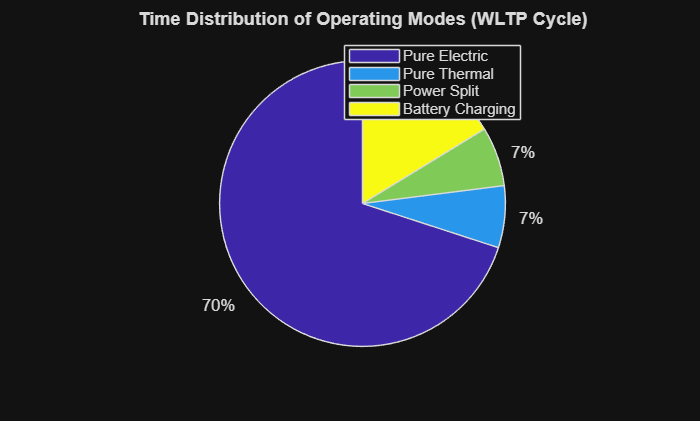

% EXTRA PLOT 1: Operating Modes Distribution
% Calculate the time spent in each operating mode by analyzing the array of
% the engine split factor alpha
% Count the number of seconds for each condition
time_PE = sum(prob_penalty.ControlProfile{2,1} == 0); % Pure Electric: alpha is exactly 0
time_PT = sum(prob_penalty.ControlProfile{2,1} == 1); % Pure Thermal: alpha is exactly 1
time_PS = sum(prob_penalty.ControlProfile{2,1} > 0 & prob_penalty.ControlProfile{2,1} < 1); % Power Split: alpha is between 0 and 1
time_BC = sum(prob_penalty.ControlProfile{2,1} > 1); % Battery Charging: alpha is strictly greater than 1

% Create the Pie Chart
figure
labels = {'Pure Electric', 'Pure Thermal', 'Power Split', 'Battery Charging'};
% The pie function automatically calculates the percentages based on the given array
pie([time_PE, time_PT, time_PS, time_BC]);
legend(labels)
title('Time Distribution of Operating Modes (WLTP Cycle)');

The pie chart illustrates the temporal distribution among the operating modes for the drivability-optimized simulation. The pure electric mode remains dominant, accounting for approximately 70% of the total cycle time. Regarding the engine modes, the time shares are symmetrically distributed, with both pure thermal and power-split operations converging around 7% each. This trend indicates that while the engine is activated less frequently, its operations are concentrated at highly efficient steady-state points, resulting in a significantly different time allocation compared to the baseline execution.

## SOC profile, Gear profile and Engine State profile

The three figures below provide a comparative analysis of the two control strategies, focusing specifically on the metrics targeted by the drivability requirements.

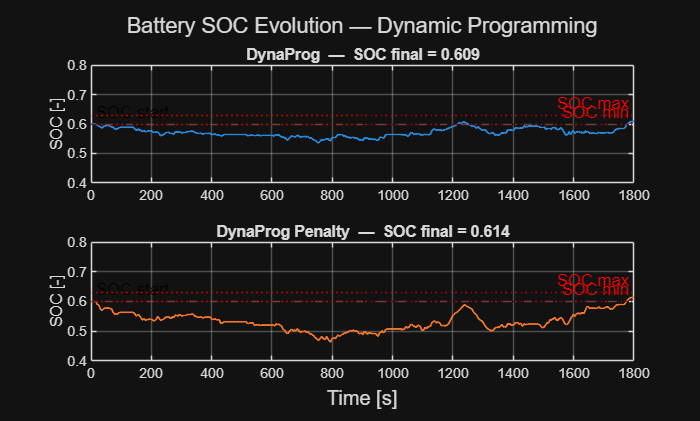

%% SOC trajectory — DynaProg and DynaProg with penalty
SOC_traj = {prob.StateProfile{1}(:), prob_penalty.StateProfile{1}(:)};
names    = {'DynaProg' 'DynaProg Penalty'};
cols     = lines(2);

figure('Name','SOC trajectory - Dynamic Programming','NumberTitle','off')
tg = tiledlayout(2,1);
for i = 1:2
    s = SOC_traj{i};                      % soc trajectory 
    t = mission.time_s(1:numel(s));          

    nexttile
    plot(t, s, 'LineWidth', 1.1, 'Color', cols(i,:))
    hold on
    yline(SOC_0,          'k--', 'SOC start', 'LabelHorizontalAlignment','left');
    yline(SOC_bounds(1),  'r:',  'SOC min', 'LabelHorizontalAlignment','right');
    yline(SOC_bounds(2),  'r:',  'SOC max', 'LabelHorizontalAlignment','right');
    hold off
    grid on, box on
    ylim([0.4 0.8]); ylabel('SOC [-]')
    title(sprintf('%s  —  SOC final = %.3f', names{i}, s(end)))
end
xlabel(tg, 'Time [s]')
title(tg, 'Battery SOC Evolution — Dynamic Programming')

***Battery SOC trajectory for the two strategies***. Both simulations exhibit a charge-sustaining behavior, terminating with a value of SOC final near to the initial 60% threshold ( $0.609$ for the baseline and $0.614$ for the drivability-optimized run). In the baseline case, the SOC is restricted to a narrow interval between $0.55$ and $0.61$. Conversely, the drivability-optimized SOC undergoes wider excursions, dropping to a local minimum of approximately $0.46$ mid-cycle before recovering. This extended operating window is a direct consequence of the engine-start penalty: by suppressing transient charging events, the battery undergoes deeper depletion between sustained engine operations. Furthermore, the expanded final constraint interval of $[0.60, 0.63]$ provides the necessary flexibility for the SOC to return above $0.60$ at the end of the cycle without inducing high-frequency terminal gear transitions.

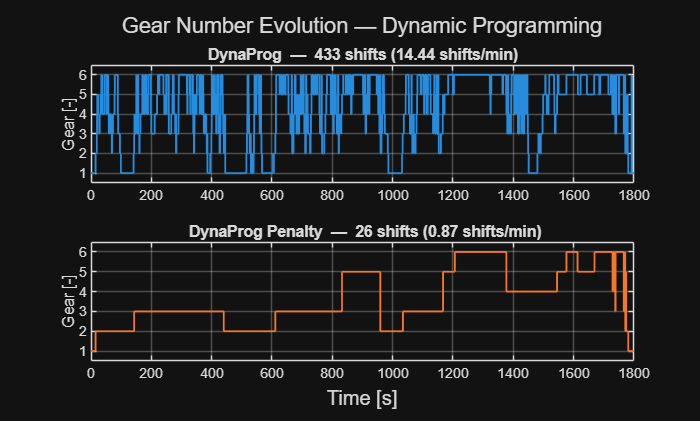

%% Gear profile — DynaProg and DynaProg with penalty
gears    = {prof.vehPrf.gearNumber, prof_penalty.vehPrf.gearNumber};
names    = {'DynaProg' ' DynaProg Penalty'};
cols     = lines(2);
gearShiftAvg = zeros(2,1);
figure('Name','Gear profile - Dynamic Programming','NumberTitle','off')
tg = tiledlayout(2,1);
for i = 1:2
    g  = gears{i};
    t  = mission.time_s(1:end-1);
    nS = sum(diff(g) ~= 0);                                  % n° of shifts
    gearShiftAvg(i)= nS/t(end)*60;

    nexttile
    stairs(t, g, 'LineWidth', 1.1, 'Color', cols(i,:))
    grid on, box on
    ylim([0.5 6.5]); yticks(1:6); ylabel('Gear [-]')
    title(sprintf('%s  —  %d shifts (%.2f shifts/min)', names{i}, nS,gearShiftAvg(i)))
end
xlabel(tg, 'Time [s]')
title(tg, 'Gear Number Evolution — Dynamic Programming')

***Gear number trajectory for the two strategies.*** The baseline simulation produces 433 gear shifts (14.44 events/min), resulting in a profile severely affected by chattering. In contrast, the drivability-optimized run executes only 26 shifts (0.87 events/min), representing a reduction of approximately 94%, and exhibits a stable, staircase-like trajectory that correlates with vehicle velocity. Consequently, the target constraint of fewer than one gear shift per minute is successfully satisfied.

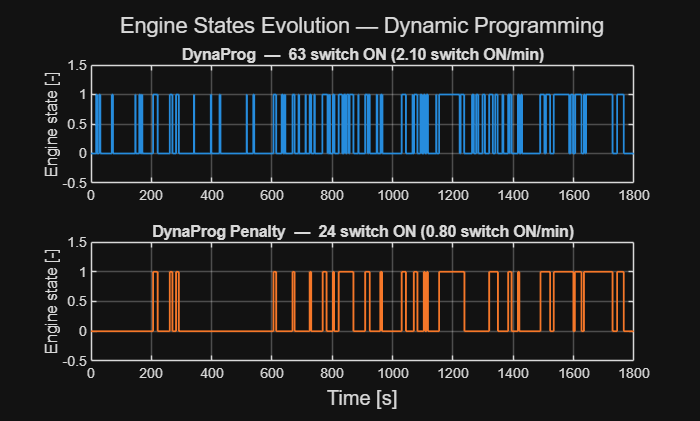

% Engine State profile — DynaProg and DynaProg with penalty

engine_state_current = prob.ControlProfile{2,1} > 0;
t  = mission.time_s(1:end-1);
engine_state_current_penalty = prob_penalty.ControlProfile{2,1}>0;
epsilon    = {double(engine_state_current), double(engine_state_current_penalty)};
names    = {'DynaProg' 'DynaProg Penalty'};
engineStartAvg=zeros(2,1);
figure('Name','Engine State profile - Dynamic Programming','NumberTitle','off')
tg = tiledlayout(2,1);
for i = 1:2
    e  = epsilon{i};
    nStart = sum(diff(e) == 1);                             % n° of engine starts
    engineStartAvg(i) = nStart/t(end)*60;

    nexttile
    stairs(t, e, 'LineWidth', 1.1, 'Color', cols(i,:))
    grid on, box on
    ylim([-0.5 1.5]); ylabel('Engine state [-]')
    title(sprintf('%s  —  %d switch ON (%.2f switch ON/min)',names{i}, nStart,engineStartAvg(i)))
end
xlabel(tg, 'Time [s]')
title(tg, 'Engine States Evolution — Dynamic Programming')

***Engine State trajectory for the two strategies.*** The baseline run activates the engine 63 times (2.10 events/min), producing transient and fragmented operations. Conversely, the drivability-optimized formulation restricts the activations to 24 instances (0.80 events/min), achieving a reduction of approximately 62%, and sustains engine operation over extended, continuous intervals. Consequently, the target constraint of fewer than one engine start per minute is successfully satisfied.

## Results analysis

The table below compares the two strategies on the WLTP. The drivability run uses c1 = 0.6 and c2 = 0.3.

- Gear shifts: base 433 (14.44/min), drivability 26 (0.87/min). Target < 1/min: met with drivability.

- Engine starts: base 63 (2.10/min), drivability 24 (0.80/min). Target < 1/min: met with drivability.

- Final SOC: base 0.609, drivability 0.614. Both >= 0.60.

- Fuel economy: base 4.5634 l/100km, drivability 4.6377 l/100km.

### Drivability Behavior

The penalty cuts gear shifts by about 94% and engine starts by about 62%, bringing both indicators below one event per minute. The qualitative change is just as important as the numbers: 

- Regarding the gear shifting behavior, the baseline profile resembles high-frequency numerical noise, where the solver continuously oscillates between adjacent gears to track minimal fuel flow variations. Conversely, the penalised profile of gear number evolution displays a clean, stable staircase trajectory. The transmission holds each gear during sustained acceleration phases and performs shifts exclusively when a substantial change in vehicle speed demands a new operating point.

- A similar transition is observed in the engine state profile. The baseline strategy exhibits a highly fragmented operation, pulsing the internal combustion engine on and off for very short bursts. In the drivability-constrained run, the engine remains active in solid, continuous blocks of time. Once the optimizer pays the fixed activation cost c2, it maximizes the utility of that start by keeping the engine on and operating along its optimal operating line.

 We obtain this without any heuristic shift schedule or minimum-on-time rule; the behavior comes out of the optimisation because we priced it into the stage cost.

### Fuel economy and the cost of drivability

Drivability is not free. The penalty pushes the solution away from the pure fuel optimum, so the drivability run is expected to use at least as much fuel as the base run for the same final SOC. Consequently, the drivability run consumes slightly more fuel (4.5634 → 4.6377 l/100km, +1.6%). When comparing them, note that the two runs end at slightly different SOC (0.609 against 0.614), because the drivability run stores a higher amount of electrical energy in the battery by the end of the cycle.

A formal SOC-balancing or equivalent-fuel correction would be expected to reduce the apparent gap further. The headline is a large drivability gain for a small fuel penalty, which is the trade-off the assignment is about. Furthermore, as quantified by the trade-off curves above, the selected gains are the smallest that satisfy the requirement.

### SOC behavior

The base strategy keeps the SOC in a narrow band because it can afford to switch the engine on whenever a short top-up is locally cheapest. Once each engine start is heavily penalised via the fixed cost c2, this localized tactical approach becomes macroscopically expensive. Consequently, the drivability-constrained strategy elects to let the SOC drop significantly further, reaching a minimum of approximately 0.46 at around $t = 800\text{ s}$, and subsequently recharges the battery during fewer, longer, and more sustained engine runs. The deeper mid-cycle dip is therefore a consequence of the start penalty, not a sign of a worse solution. 

The selection of the final SOC constraints plays a crucial role in managing this behavior at the end of the driving horizon:

- In the baseline run, the system easily satisfies the tight target of [0.60 0.62], landing smoothly at a final value of 0.609.

- The wider final SOC band is what makes this feasible without end-of-cycle corrections. Conversely, when penalties are active, forcing the terminal state into that same narrow window causes severe end-of-cycle numerical corrections, as the solver is compelled to trigger rapid gear shifts and engine activations in the final seconds just to force the SOC into the target. Widening the terminal boundary condition to [0.60 0.63] provides the necessary numerical slack. As a result, the penalised strategy safely sustains the battery charge, achieving a final SOC of 0.614 ( $\sigma_N \ge 60\%$ ) while completely eliminating late, non-drivable corrective actions.

### **Computational Effort and Grid scaling analysis**

Adding the two drivability states changes how heavy the problem is to solve. The state grid grows from 81 nodes (SOC alone) to 81 × 6 × 2 = 972 nodes (SOC, previous gear, previous engine state). This weighs on the backward phase, which builds the cost-to-go over the whole state grid at every second of the cycle: its cost grows roughly in proportion to the number of grid nodes, so the drivability run is markedly heavier to solve than the base one. The forward phase behaves differently. Once the cost-to-go is known, it simulates a single optimal trajectory from the initial state (sigma_0 = 60%), evaluating one control choice per second, so its cost depends on the cycle length and not on the size of the state grid. This is the practical face of the curse of dimensionality: every extra state multiplies the backward workload, while the forward simulation stays cheap.

### Operating points 

On the engine map, the loaded points stay near the Optimal Operating Line (OOL) in both runs, demonstrating that when the engine works, it operates efficiently under either strategy. The core difference is that the drivability run eliminates the scattered low-load points that the base run produced through its numerous brief starts.  

The operating mode distribution shifts noticeably between the two configurations: while pure electric traction remains dominant in both cases ( ~ 68% in the base run and ~ 70% in the penalty configuration ), the key discrepancy lies within the engine-on modes. In the baseline run, the engine-on time is highly fragmented across many short pulses of pure thermal and power-split operation. Conversely, in the drivability run, these brief intervals consolidate into fewer, longer stretches, redistributing the time more evenly between pure thermal and power-split conditions. 

### Conclusion 

Casting the previous gear and the previous engine state as extra states, and pricing gear shifts and engine starts into the stage cost, turns the fuel-optimal but undrivable policy into a drivable one that still operates the engine efficiently. With c1 = 0.6 and c2 = 0.3 and a final SOC band of [0.60 0.63], both drivability requirements are met at a small fuel cost, and the result is obtained from the optimisation itself rather than from added heuristics.